% Import features extracted files of emotions H, F, S, and C
H = importdata('../Data/Feature Extracted/MFCC_HAPPY.mat'); 
F = importdata('../Data/Feature Extracted/MFCC_FEAR.mat');
S = importdata('../Data/Feature Extracted/MFCC_SAD.mat');
C = importdata('../Data/Feature Extracted/MFCC_CALM.mat');

% Combine datasets with targets
x = addTargetsAndCombine(H, F, S, C);

Size of combined dataset x: 912  139


Accuracy for fold 1: 96.7033%


Confusion Matrix for fold 1:


    42     1     0     0
     2    40     1     0
     1     0    36     0
     1     0     0    58



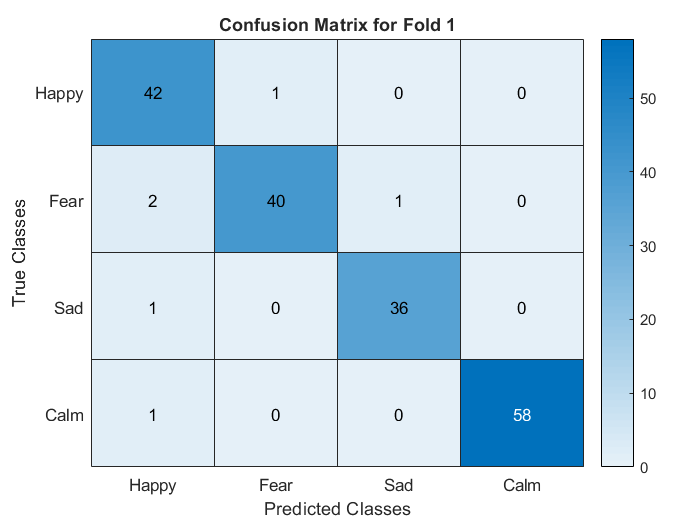

Accuracy for fold 2: 98.3516%


Confusion Matrix for fold 2:


    48     0     2     0
     1    42     0     0
     0     0    41     0
     0     0     0    48



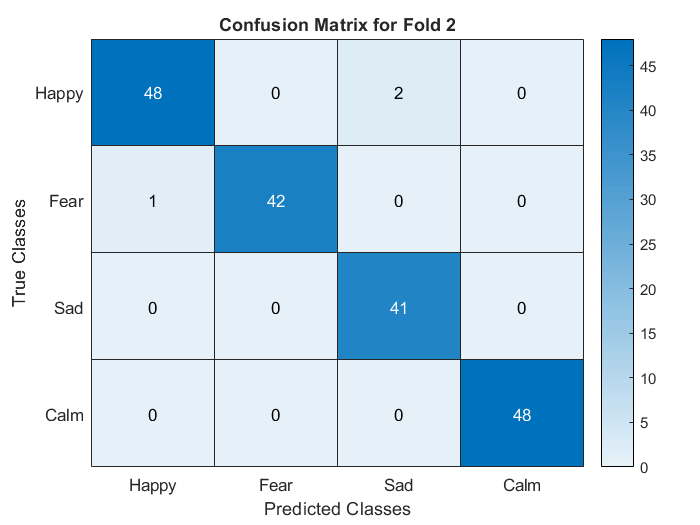

Accuracy for fold 3: 96.7033%


Confusion Matrix for fold 3:


    43     0     0     0
     0    49     0     0
     2     1    48     1
     1     1     0    36



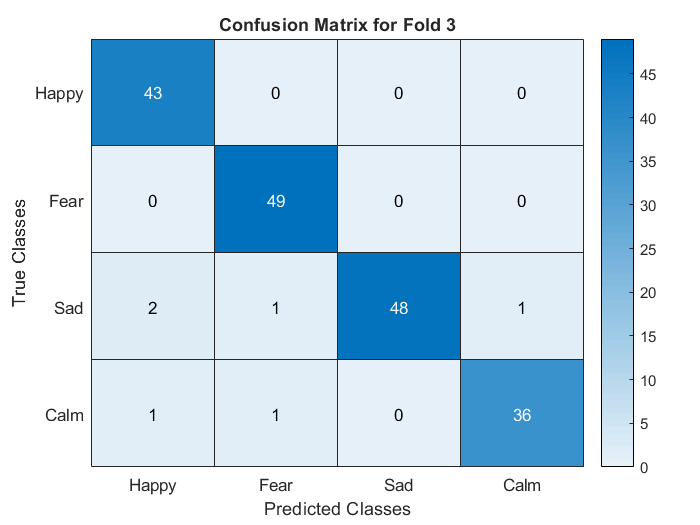

Accuracy for fold 4: 96.1538%


Confusion Matrix for fold 4:


    32     1     1     1
     0    47     0     1
     2     0    52     0
     1     0     0    44



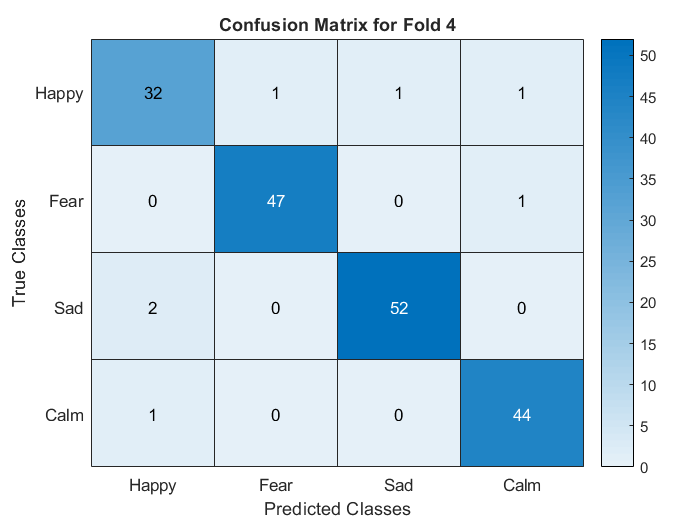

Accuracy for fold 5: 99.4505%


Confusion Matrix for fold 5:


    57     0     0     0
     0    44     0     0
     0     1    43     0
     0     0     0    37



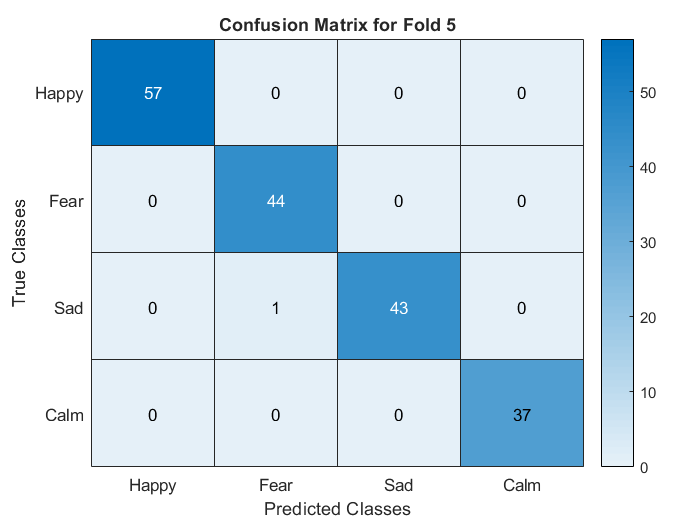

% Randomize x
[row, col] = size(x);
R = randperm(row);
rx = x(R, :); % Randomize rows

% Initialize variables to store accuracy and models
perac = zeros(1, 5); % To store accuracy for each fold
px = 0; % Initialize best accuracy

% Dividing x into 5 folds
for i = 1:5
    [trainS, tgTrainS, testS, tgTestS] = divsig1(rx, i);
    
    % Ensure tgTrainS and tgTestS are column vectors
    tgTrainS = tgTrainS(:); % Convert to column vector
    tgTestS = tgTestS(:);   % Convert to column vector

    if size(trainS, 1) ~= length(tgTrainS)
        error('Number of observations in trainS and tgTrainS do not match.');
    end
    
    if size(testS, 1) ~= length(tgTestS)
        error('Number of observations in testS and tgTestS do not match.');
    end

    % KNN classification
    mdl = fitcknn(trainS, tgTrainS, 'NumNeighbors', 5); % Adjust 'NumNeighbors' as needed
    y = predict(mdl, testS);
    
    % Calculate accuracy
    perAcc = sum(y == tgTestS) / length(tgTestS) * 100; % Accuracy
    perac(i) = perAcc;

    % Display accuracy for the current fold
    disp(['Accuracy for fold ', num2str(i), ': ', num2str(perAcc), '%']);

    % Calculate and display confusion matrix
    cm = confusionmat(tgTestS, y);
    disp(['Confusion Matrix for fold ', num2str(i), ':']);
    disp(cm);

    % Visualize the confusion matrix
    figure;
    heatmap(cm, 'Title', ['Confusion Matrix for Fold ', num2str(i)], ...
            'XLabel', 'Predicted Classes', 'YLabel', 'True Classes', ...
            'CellLabelFormat', '%d', ...
            'XDisplayLabels', {'Happy', 'Fear', 'Sad', 'Calm'}, ...
            'YDisplayLabels', {'Happy', 'Fear', 'Sad', 'Calm'});
    
    % Save the best model based on accuracy
    if i == 1 || perAcc > px
        mdlx = mdl;
        px = perAcc;
    end
end

%% Save the best model
save('mdl', 'mdlx');
% 
predictions = predict(mdlx, testS);

% Calculate accuracy
accuracy = sum(predictions == tgTestS) / length(tgTestS) * 100;

% Display the accuracy
disp(['Accuracy of the model on new data: ', num2str(accuracy), '%']);

Accuracy of the model on new data: 99.4505%


%% Confusion matrix
cm = confusionmat(tgTestS, predictions);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(cm);

    57     0     0     0
     0    44     0     0
     0     1    43     0
     0     0     0    37



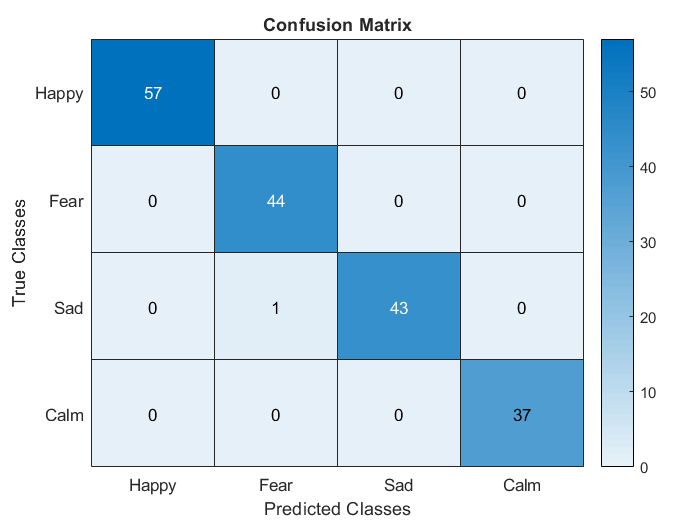

% Visualize the confusion matrix
figure;
heatmap(cm, 'Title', 'Confusion Matrix', ...
        'XLabel', 'Predicted Classes', 'YLabel', 'True Classes', ...
        'CellLabelFormat', '%d', ...
        'XDisplayLabels', {'Happy', 'Fear', 'Sad', 'Calm'}, ...
        'YDisplayLabels', {'Happy', 'Fear', 'Sad', 'Calm'});

%% Loading the model

% Load the saved model
loadedData = load('mdl.mat');

% Access the model
mdlxz = loadedData.mdlx;  

% Optionally, display the model to confirm it's loaded
disp(mdlxz);

  ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3 4]
           ScoreTransform: 'none'
          NumObservations: 730
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods



%% 
predictions = predict(mdlxz, testS);

% Calculate accuracy
accuracy = sum(predictions == tgTestS) / length(tgTestS) * 100;

% Display the accuracy
disp(['Accuracy of the model on new data: ', num2str(accuracy), '%']);

Accuracy of the model on new data: 99.4505%


%% Confusion matrix
cm = confusionmat(tgTestS, predictions);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(cm);

    57     0     0     0
     0    44     0     0
     0     1    43     0
     0     0     0    37




% Visualize the confusion matrix
figure;
heatmap(cm, 'Title', 'Confusion Matrix', ...
        'XLabel', 'Predicted Classes', 'YLabel', 'True Classes', ...
        'CellLabelFormat', '%d', ...
        'XDisplayLabels', {'Happy', 'Fear', 'Sad', 'Calm'}, ...
        'YDisplayLabels', {'Happy', 'Fear', 'Sad', 'Calm'});